dataFolder = '/GEE_30m';
labelIDs = [0 1];
pixelLabelIDs = {0 1};
classes = ["no_label", "flood"];
imgDir = fullfile(pwd, dataFolder, '/train', 'images');

imds = imageDatastore(imgDir);
labelDir = fullfile(pwd, dataFolder, '/train', 'labels');
pxds = pixelLabelDatastore(labelDir, classes, pixelLabelIDs);

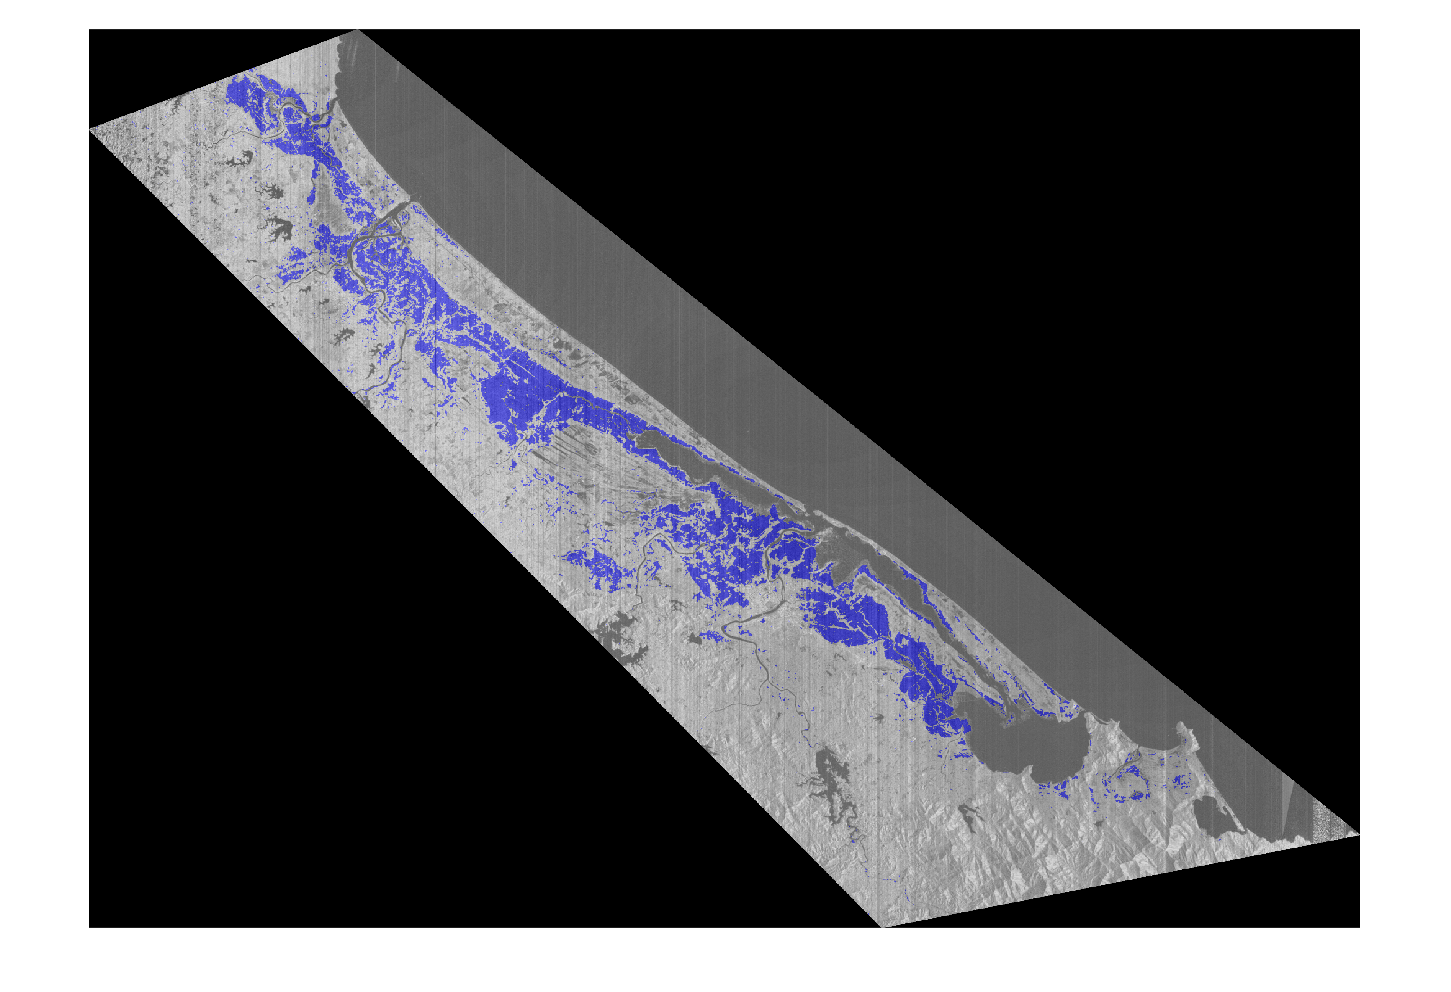

i = readimage(imds, 1);
c = readimage(pxds, 1);
i1 = normalize(i(:,:,1), 'range', [0 1]);
c1 = double(c);
b = labeloverlay(i1,c1,'ColorMap', [0.7 0.7 0.7; 0 0 1]);
imshow(b);

tbl = countEachLabel(pxds)

tbl = 2×3 table
        Name        PixelCount    ImagePixelCount
    ____________    __________    _______________

    {'no_label'}    5.3147e+07      5.4805e+07   
    {'flood'   }    1.6583e+06      5.4805e+07   


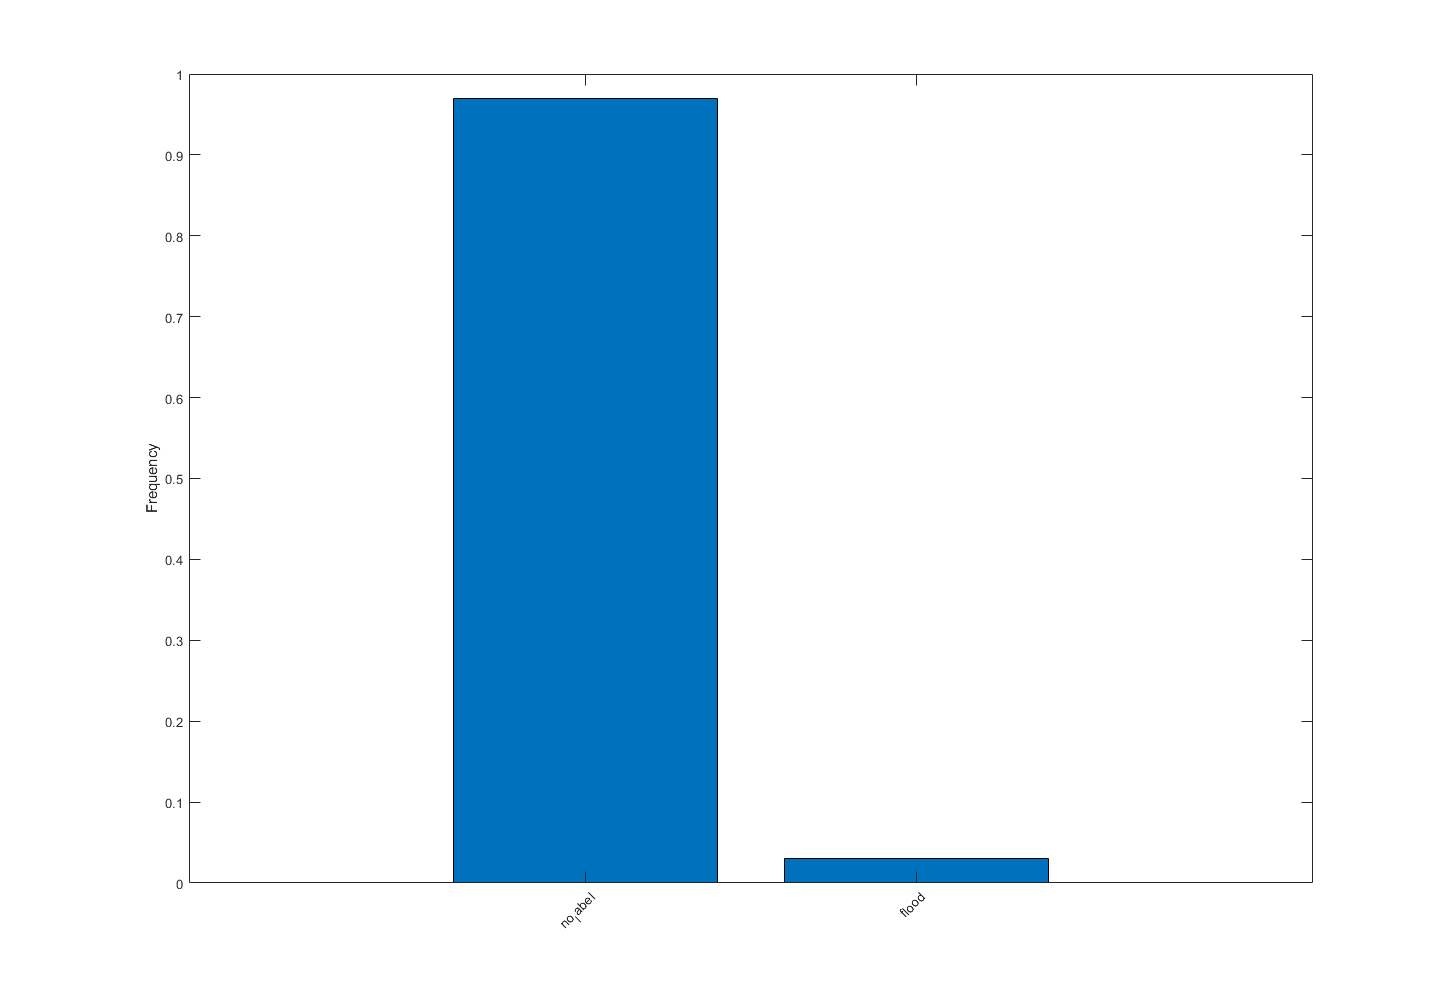

frequency = tbl.PixelCount/sum(tbl.PixelCount);

bar(1:numel(classes),frequency)
xticks(1:numel(classes)) 
xticklabels(tbl.Name)
xtickangle(45)
ylabel('Frequency')

imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount;
classWeights = median(imageFreq) ./ imageFreq

classWeights =     0.5156
   16.5241


inputTileSize = [300, 300, 2];
patchesPerImage = 400;
dsTrain = imbalanceRandomPatchExtractionDatastore(imds, pxds, inputTileSize(1:2), 0.4, 1000, "PatchesPerImage", patchesPerImage);
inputBatch = preview(dsTrain);
disp(inputBatch)

        InputImage        ResponsePixelLabelImage
    __________________    _______________________

    {300×300×2 double}     {300×300 categorical} 
    {300×300×2 double}     {300×300 categorical} 
    {300×300×2 double}     {300×300 categorical} 
    {300×300×2 double}     {300×300 categorical} 
    {300×300×2 double}     {300×300 categorical} 
    {300×300×2 double}     {300×300 categorical} 
    {300×300×2 double}     {300×300 categorical} 
    {300×300×2 double}     {300×300 categorical} 



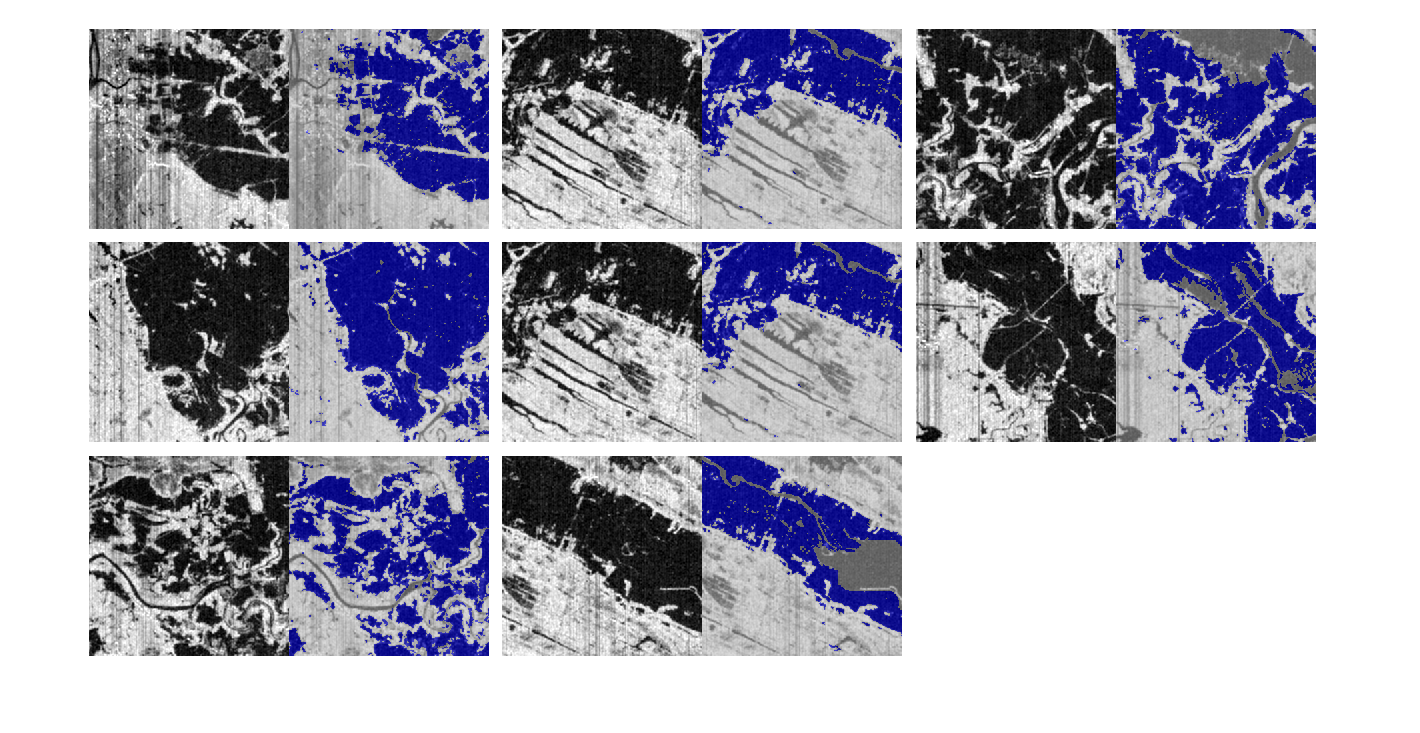

showImageWithLabel(inputBatch)

valImgDir = fullfile(pwd, dataFolder, '/validate', 'images');
valImds = imageDatastore(valImgDir);
valLabelDir = fullfile(pwd, dataFolder, '/validate', 'labels');
valPxds = pixelLabelDatastore(valLabelDir, classes, pixelLabelIDs);
dsValidate = imbalanceRandomPatchExtractionDatastore(imds, pxds, inputTileSize(1:2), 0.99, 1000, "PatchesPerImage", patchesPerImage);

% pxLayer = dicePixelClassificationLayer('Name','dice-Pixel-Classification-Layer','Classes',tbl.Name);
% pxLayer = pixelClassificationLayer('Name','Pixel-Classification-Layer','Classes',tbl.Name,'ClassWeights',classWeights);
% lgraph = createUnet(inputTileSize, numel(classes), pxLayer);
% lgraph = unetLayers(inputTileSize, numel(classes), "EncoderDepth", 4, "FilterSize",3);
% lgraph = replaceLayer(lgraph, 'Segmentation-Layer', pxLayer);
% disp(lgraph.Layers)

initialLearningRate = 0.05;
maxEpochs = 100;
minibatchSize = 3;
l2reg = 0.0001;

options = trainingOptions('sgdm',...
    'InitialLearnRate',initialLearningRate,...
    'ValidationData', dsValidate,...
    'Momentum',0.9,...
    'L2Regularization',l2reg,...
    'MaxEpochs',maxEpochs,...
    'MiniBatchSize',minibatchSize,...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropFactor', 0.1,...
    'LearnRateDropPeriod', 2,...
    'Shuffle','every-epoch',...
    'GradientThresholdMethod','l2norm',...
    'GradientThreshold',0.05,...
    'Plots','training-progress',...
    'VerboseFrequency',20,...
    "ExecutionEnvironment","gpu");
%     "CheckpointPath", strcat(pwd, dataFolder, '/checkpoint'));

doTraining = true;
if doTraining
    modelDateTime = datestr(now,'dd-mmm-yyyy-HH-MM-SS');
    [net,info] = trainNetwork(dsTrain,lgraph,options);
    save(['savedUnet-' modelDateTime '-Epoch-' num2str(maxEpochs) '.mat'],'net','options');
end

Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:50 |       57.27% |       83.92% |       0.3630 |       0.6742 |          0.0500 |


|       1 |          20 |       00:01:02 |       64.82% |              |       0.3718 |              |          0.0500 |


|       1 |          40 |       00:01:12 |       67.00% |              |       0.3801 |              |          0.0500 |


|       1 |          50 |       00:02:16 |       60.89% |       86.68% |       0.3523 |       0.7056 |          0.0500 |


|       1 |          60 |       00:02:23 |       56.48% |              |       0.3597 |              |          0.0500 |


|       1 |          80 |       00:02:34 |       63.79% |              |       0.3643 |              |          0.0500 |


|       1 |         100 |       00:03:30 |       59.36% |       85.32% |       0.3679 |       0.6837 |          0.0500 |


|       1 |         120 |       00:03:42 |       55.67% |              |       0.3668 |              |          0.0500 |


|       1 |         140 |       00:03:53 |       48.04% |              |       0.3797 |              |          0.0500 |


|       1 |         150 |       00:04:42 |       52.53% |       82.81% |       0.3365 |       0.6452 |          0.0500 |


|======================================================================================================================|
